fid = fopen('vsmall.txt');
x=fread(fid,'*char')

x = 99×1 char array
    'H'
    'e'
    'l'
    'l'
    'o'
    ' '
    'w'
    'o'
    'r'
    'l'
    'd'
    '.'
    '←'
    '↵'
    'T'
    'h'
    'i'
    's'
    ' '
    'i'
    's'
    ' '
    'a'
    'n'
    ' '
    'e'
    'x'
    'a'
    'm'
    'p'
    'l'
    'e'
    ' '
    't'
    'e'
    'x'
    't'
    ' '
    'f'
    'i'
    'l'
    'e'
    '.'
    ' '
    'I'
    ' '
    'w'
    'a'
    'n'
    't'
    ' '
    't'
    'o'
    ' '
    's'
    'e'
    'n'
    'd'
    ' '
    't'
    'h'
    'i'
    's'
    ' '
    'u'
    's'
    'i'
    'n'
    'g'
    ' '
    'O'
    'p'
    't'
    'i'
    'c'
    'a'
    'l'
    ' '
    'C'
    'a'
    'm'
    'e'
    'r'
    'a'
    ' '
    'C'
    'o'
    'm'
    'm'
    'u'
    'n'
    'i'
    'c'
    'a'
    't'
    'i'
    'o'
    'n'
    '.'


binary = dec2bin(x,8)

binary = 99×8 char array
    '01001000'
    '01100101'
    '01101100'
    '01101100'
    '01101111'
    '00100000'
    '01110111'
    '01101111'
    '01110010'
    '01101100'
    '01100100'
    '00101110'
    '00001101'
    '00001010'
    '01010100'
    '01101000'
    '01101001'
    '01110011'
    '00100000'
    '01101001'
    '01110011'
    '00100000'
    '01100001'
    '01101110'
    '00100000'
    '01100101'
    '01111000'
    '01100001'
    '01101101'
    '01110000'
    '01101100'
    '01100101'
    '00100000'
    '01110100'
    '01100101'
    '01111000'
    '01110100'
    '00100000'
    '01100110'
    '01101001'
    '01101100'
    '01100101'
    '00101110'
    '00100000'
    '01001001'
    '00100000'
    '01110111'
    '01100001'
    '01101110'
    '01110100'
    '00100000'
    '01110100'
    '01101111'
    '00100000'
    '01110011'
    '01100101'
    '01101110'
    '01100100'
    '00100000'
    '01110100'
    '01101000'
    '01101001'
    '01110011'
    '00100000'
    '01110101'


binary_t=transpose(binary);
bin=binary_t(:)-'0'  ;
data=zeros(223*8,1);
data(1:792)=bin;

encData=rsencoder(data)

encData =      1
     1
     0
     1
     1
     0
     0
     1
     1
     1


numFrames = 0.6641

numAdditionalSymbols = 1032

bitstream =      1
     1
     0
     1
     1
     0
     0
     1
     1
     1


numcompleteframes = 1

image = image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

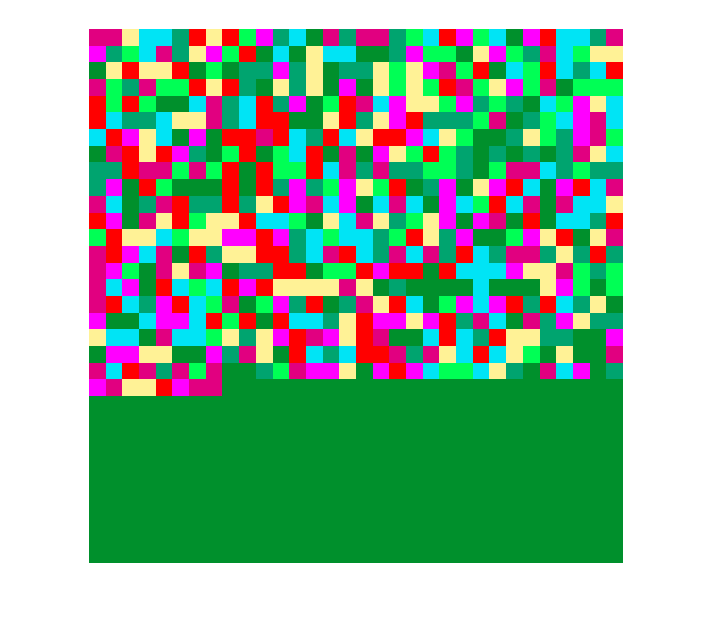

filename = "./images/1.jpg"

image = image(:,:,1) =

  Columns 1 through 999

    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824 

image=generateImages(encData,32,50)

erasuresvector=zeros(255,1)
[binaryStream,errs] = rsdecoder(encData,erasuresvector)

plotChromaticity


for i=1:223
    binar(i,:)=data((i-1)*8+1:(i)*8)'
end
binaryR = char(bin2dec(binary));
filename='received2.txt';
fid = fopen(filename,'w');
fprintf(fid,'%s',binaryR);
fclose(fid);

n=255;
k=223;
rsencoder = comm.RSEncoder(n,k,'BitInput',true);
rsdecoder = comm.RSDecoder(n,k,'ErasuresInputPort',true,'NumCorrectedErrorsOutputPort',true,'BitInput',true);
data=randi([0 1],223*8,1)

data =      1
     1
     0
     1
     1
     0
     0
     1
     1
     1


encData=rsencoder(data)

encData =      1
     1
     0
     1
     1
     0
     0
     1
     1
     1


a=0.579
b=0.329
z=1-a-b
syms x y
eqn1=(a-1)*x+a*y+a*z==0
eqn2=(b-1)*y+b*x+y*z==0
[A,B]=equationsToMatrix([eqn1,eqn2],[x,y])
an=linsolve(A,B)
xyz2rgb([double(an(1)) double(an(2)) double(z)])

encDataR=encData;
encDataR(1)=0
encDataR(2)=0
%encDataR(3)=0
erasuresvector=zeros(n,1)
erasuresvector(1:2)=1

[estData,errs] = rsdecoder(encDataR,erasuresvector)

cam = webcam(3)
preview(cam)

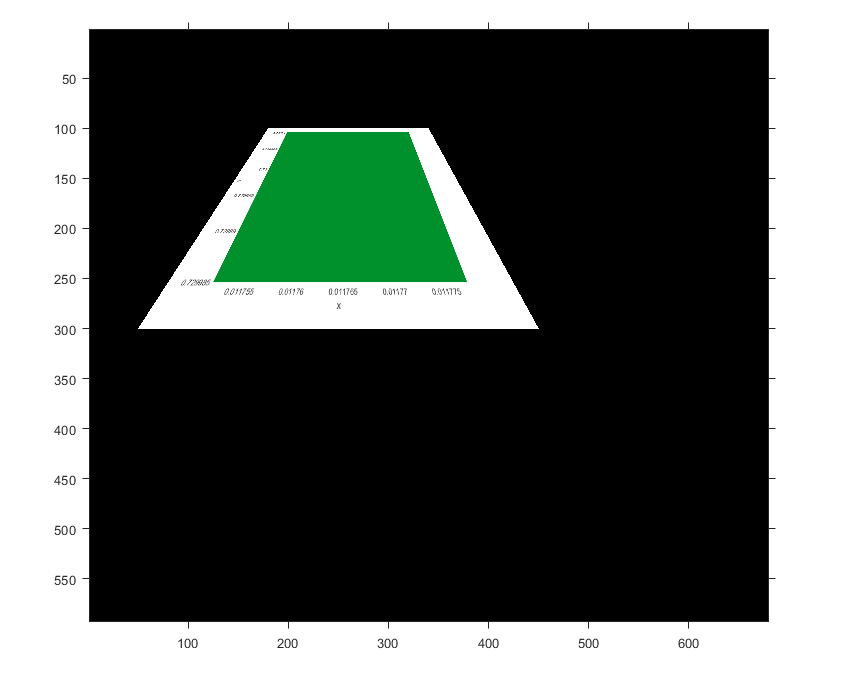

img = imread('s0.png')
%// Create perspective transformation that warps the original 
%// image coordinates to the trapezoid
movingPoints = [1 1; size(img,2) 1; 1 size(img,1); size(img,2) size(img,1)];
fixedPoints = [180 100; 340 100; 50 300; 450 300];
tform = fitgeotrans(movingPoints, fixedPoints, 'Projective');

%// Create a reference coordinate system where the extent is the size of
%// the image
RA = imref2d([size(img,1) size(img,2)], [1 size(img,2)], [1 size(img,1)]);

%// Warp the image
[out,r] = imwarp(img, tform, 'OutputView', RA);

%// Show the image and turn off the axes
imshow(out, r);


axis off;

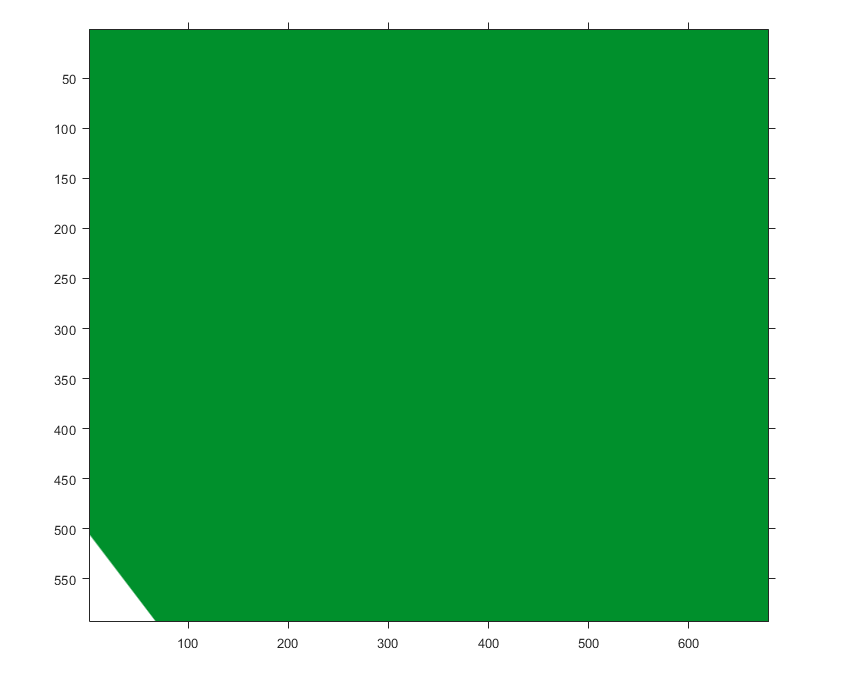


fixedPoints = [1 1; size(img,2) 1; 1 size(img,1); size(img,2) size(img,1)];
movingPoints = [180 100; 340 100; 50 300; 450 300];
tform = fitgeotrans(movingPoints, fixedPoints, 'Projective');

%// Create a reference coordinate system where the extent is the size of
%// the image
RA = imref2d([size(img,1) size(img,2)], [1 size(img,2)], [1 size(img,1)]);

%// Warp the image
[out,r] = imwarp(img, tform, 'OutputView', RA);

%// Show the image and turn off the axes
imshow(out, r);

function image =generateImages(bitstream,size,pixelsize)
symbolsPerFrame=size*size;
numFrames=length(bitstream)/(3*symbolsPerFrame)
if (mod(numFrames,1)~=0)
    numcompleteframes=floor(numFrames);
    numAdditionalSymbols=3*((size*size)-(length(bitstream)/3-symbolsPerFrame*numcompleteframes))
    bitstream(end:end+numAdditionalSymbols)=0
    numcompleteframes=numcompleteframes+1
end
image=zeros(pixelsize*size,pixelsize*size,3,numcompleteframes) %initialize
for j=1:numcompleteframes
for i=(j-1)*size*size+1:(j)*size*size
    
    row = floor((i-1)/size)+1;
    col=(i)-(row-1)*size;
    row=mod(row,size);
    if (row==0)
        row=size;
    end
   
    symbol = num2str(bitstream(3*(i-1)+1:3*(i))');
    switch symbol
        case('0  0  0')
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=0;
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=144/255;  
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=44/255;
         case('0  0  1')
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=0;
              image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=164/255;  
              image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=111/255;
         case('0  1  0')
              image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=0;
               image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=1;  
               image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=85/255;
        case('0  1  1')
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=1;
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=242/255;  
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=150/255;
         case('1  0  0')
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=1;
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=0;  
             image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=1; 
        case('1  0  1')
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=0;
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=228/255;  
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=245/255;
        case('1  1  0')
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=225/255;
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=0;  
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=0.5;
        case('1  1  1')
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1,j)=1;
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2,j)=0;  
            image(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3,j)=0;
    end
end

 %image(:,1:100,1)=0;   %Red (dark red)

% image(:,1:100,2)=1;  %Green
% image(:,1:300,3)=1;  %Green
imgtemp=image(:,:,:,j);
 figure, imshow(imgtemp)
 filename='./images/'+string(j)+'.jpg'
 imwrite(imgtemp,filename)
end
end